# Assignment 4: Template Matching

T = imread('prototype.jpg'); % Reading in our template image

[h, w] = size(T); % Checking the size of our template image...

Photo = imread('shanghai.jpg'); % This is our main image: a photo of part of Shanghai's skyline

[H, W, l] = size(Photo)

H = 760

W = 1064

l = 3


Wallpaper = imread('wallpaper.jpg'); % This is the wallpaper which we can use to paste
% over stuff...
Wallpaper = imresize(Wallpaper, [55 36]);

% Let's pre-compute some important terms here:
Total_energy_T = sum(sum(T)) % The total energy of the template

Total_energy_T = 319835

Average_energy_T = Total_energy_T/numel(T) % The average energy of the template

Average_energy_T = 161.5328

flippedT = rot90(rot90(T)); % Rotating the template by 90 degrees twice...

Photo = rgb2gray(Photo); % Converting the image to gray-scale - now we have
% a single number in each row-column position, instead of an RGB triplet...
Padded_Photo = zeros(H+h, W+w); % Making a padded version for computation purposes
Padded_Photo(1:H, 1:W) = Photo; % And inserting the photo into the top left corner

**Computing the correlation between each sub-image and the template efficiently:**

In order to work out the correlation between each sub-image and the template, we'll use the 2D convolution sum. We could use the convolution sum inside a nested *for* loop (with the inputs being the sub-image at position (x, y), and the template), but this would be a little inefficient, as the sub-images overlap and the template is always the same, so we'd perform some computations over and over again. Instead we'll take the 2D convolution of the padded image and the template - amazingly, the correlation between any of the sub-images and the template will be contained within this big resultant matrix, and so there's no need for us to use nested *for *loops - this comes out as much quicker, too!

Big_corr_matrix = conv2(flippedT, Padded_Photo); % The correlation between a sub-image at (x, y) and the template
% is contained in this big matrix

num_corr = zeros(H, W); % This matrix stores the numerator of the correlation expression for a sub image and
% the template...

num_corr(1:H, 1:W) = Big_corr_matrix(h:H+h-1, w:W+w-1);

Next we'll want to compute the local average of the sub-images for all the positions(x, y) or row and column. One can do this efficiently using a **running sum **- the diagram below will hopefully describe my idea or approach: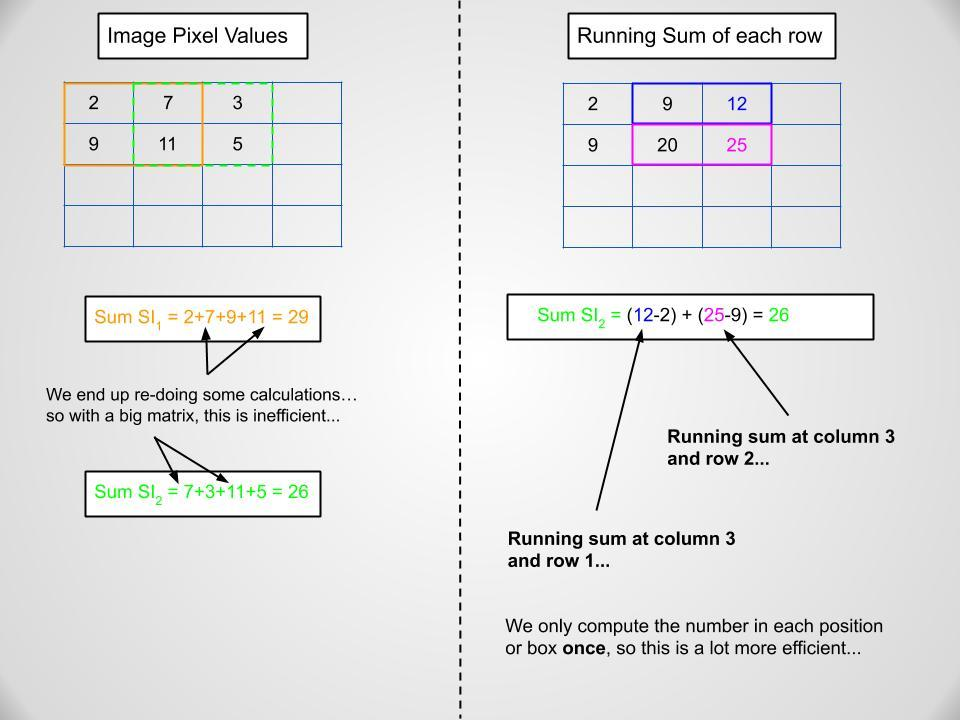

So I want to take the running sum of each row of my photo - we can use an IIR filter to do this:


$$R\ldotp S\left(n\right)=x\left(n\right)+R\ldotp S\left(n-1\right)\leftrightarrow y\left(n\right)=x\left(n\right)+y\left(n-1\right)$$


The above expression essentially means the running sum at time (n), is equal to the whatever the input value at nth spot is (i.e. x(n)) plus the running sum at time (n-1). We can use the filter( ) command to do this:

RS_matrix = filter(1, [1 -1], Photo')'; % Running sum matrix...

SI_Px_Sum = zeros(H, W+1); % A matrix representing the sum of the pixel (Px) values in the sub-image (SI)

RS_matrix = [zeros(H, 1) RS_matrix]; % Padding the matrix with zeros for indexing purposes...

for r = 1:H-h % We only goes this far, as the sub-image that starts on the next row goes outside the image...
    for c = 2:W-w+1
        SI_Px_Sum(r, c-1) = sum(RS_matrix(r:r+h-1, c+w-1)) - sum(RS_matrix(r:r+h-1, c-1)); % Subtracting the sum of running sum values, as
        % alluded to in the diagram earlier...
    end
end

f_bar = (1/numel(T)).*SI_Px_Sum; % As one would expect, to get the average we're simply dividing by the number
% of elements in the template...
Photo_sqrd = double(Photo).^2; % Squaring each element in the image, and then converting to type double for summing purposes

whole_num_corr = num_corr - Total_energy_T.*f_bar(:, 1:1064); % The full denominator expression for the correlation expression...

denom_T1 = sum(sum((T-Average_energy_T).^2)); % The first denominator term
denom_T2 = zeros(H, W); % A matrix representing the second term (T2) of the denominator

for r = 1:H-h
    for c = 1:W-w
        denom_T2(r, c) = Photo_sqrd(r, c) + w*h*f_bar(r, c);
    end
end

Corr_matrix = whole_num_corr./(sqrt(denom_T1.*denom_T2)); % Element-wise division is faster than using for loops...

[MaxVal_vec, Index_vec] = max(Corr_matrix(1:705, 1:1020)); % Looking for the pixel whose sub-image has the greatest
% correlation to the template...
Composite_matrix = [MaxVal_vec; Index_vec];

[Max_correlation, Px_column] = max(Composite_matrix(1, :))

Max_correlation = 17.1001

Px_column = 661

Px_row = Composite_matrix(2, Px_column)

Px_row = 431

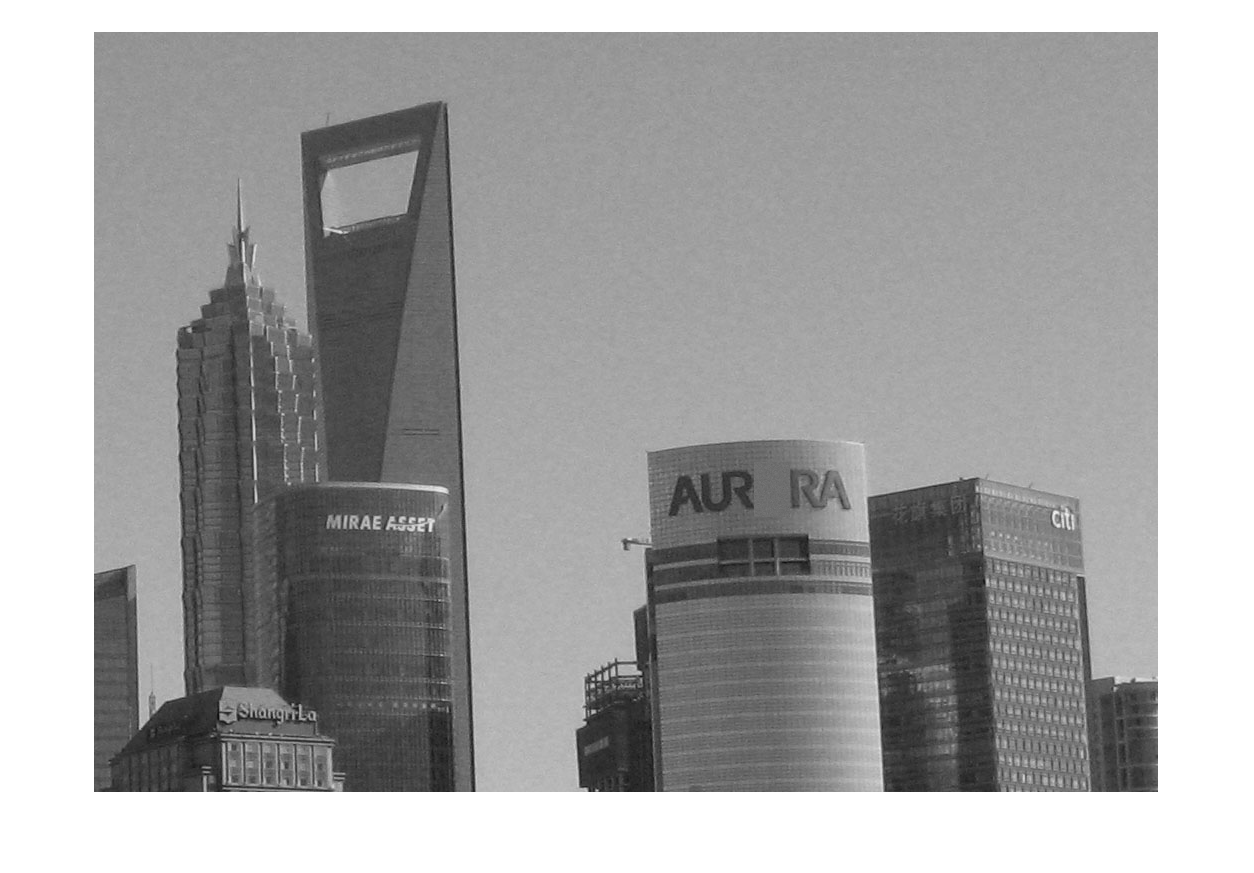


Photo(Px_row:Px_row+h-1, Px_column:Px_column+w-1) = Wallpaper; % Now applying a wallpaper to the relevant pixel
imshow(Photo) % Let's view the image to see if we've wallpapered over the 'O'

In order to get around the problem of the noise in the 'Shanghai1' image, the algorithm would need to be changed: the correlation values is very high because of the extreme values associated with the black - this shows one of the drawbacks or weaknesses of the algorithm I used - sometimes images can have a high correlation even if they're not very similar

- One could apply a filter to each sub-image in an attempt to attenuate the noise before calculating the correlation with the template

- One could check if the sub-image at the supposed pixel position is *really *the same or similar to the template: perhaps by performing element-wise substraction: if the two images really are the same then this resultant matrix should be made of relatively small values, close to zero